clear all; close all;clc;

img0 = imread('0.tif');
img4 = imread("4.tif");
img8 = imread("8.tif");
img12 = imread("12.tif");

### Preprocessing

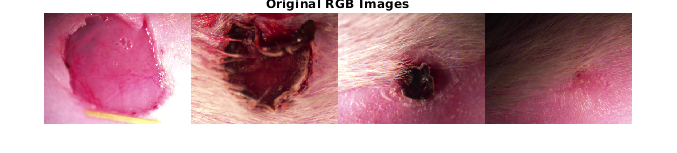

figure(1)
montage({img0,img4,img8,img12},"Size",[1,4]);
title("Original RGB Images")

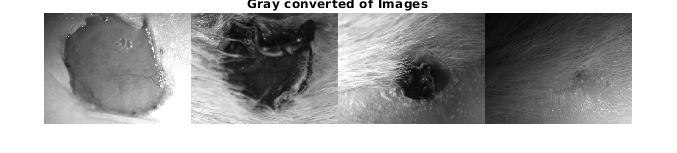

gray0 = rgb2gray(img0);
gray4 = rgb2gray(img4);
gray8 = rgb2gray(img8);
gray12 = rgb2gray(img12);
figure(2)
montage({gray0,gray4,gray8,gray12},"Size",[1,4]);
title('Gray converted of Images');

### Color Transformation

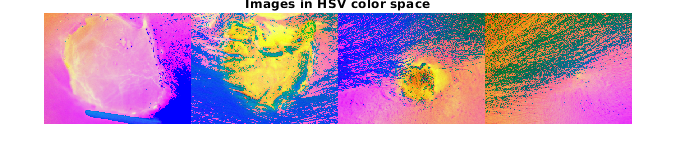

hsv0 = rgb2hsv(img0);
hsv4 = rgb2hsv(img4);
hsv8 = rgb2hsv(img8);
hsv12 = rgb2hsv(img12);
figure(3)
montage({hsv0, hsv4, hsv8, hsv12}, "Size",[1,4]);
title('Images in HSV color space');

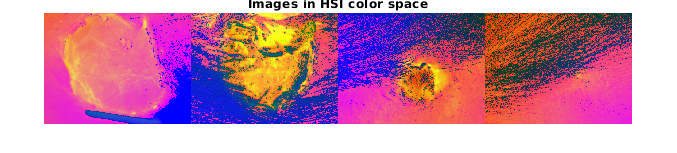

hsi0 = rgb2hsi(img0);
hsi4 = rgb2hsi(img4);
hsi8 = rgb2hsi(img8);
hsi12 = rgb2hsi(img12);
figure(4)
montage({hsi0, hsi4, hsi8, hsi12}, "Size",[1,4]);
title('Images in HSI color space');

### Segment Region of Intrest 

[bw0,seg0] = createMask0(img0);
[bw4,seg4] = createMask4(img4);
[bw8,seg8] = createMask8(img8);
[bw12,seg12] = createMask12(img12);

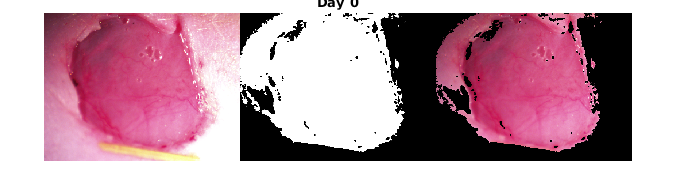

montage({img0,bw0,seg0},Size=[1,3]);title("Day 0");

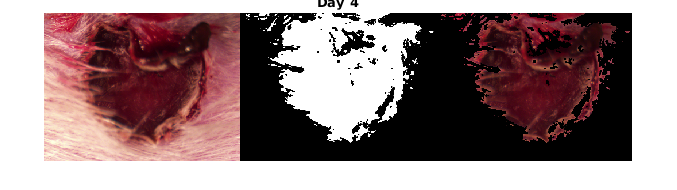

montage({img4,bw4,seg4},Size=[1,3]);title("Day 4")

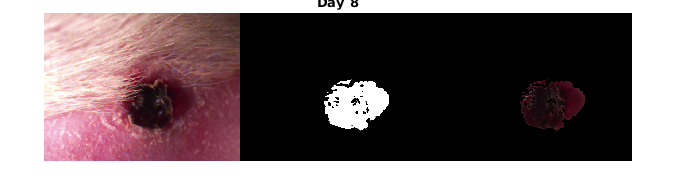

montage({img8,bw8,seg8},Size=[1,3]);title("Day 8")

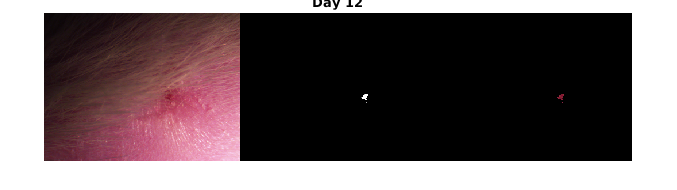

montage({img12,bw12,seg12},Size=[1,3]);title("Day 12")

### First Order Histogram based Statistical Features

Only four first order features namely **mean, standard deviation, skewness, and kurtosis** 

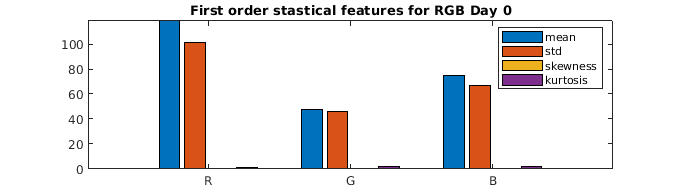

legend_given = ["mean","std","skewness","kurtosis"];
img0_fof = get_first_features(seg0);
plot_bar(img0_fof,["R","G","B"],"First order stastical features for RGB Day 0",legend_given)
img4_fof = get_first_features(seg4);
plot_bar(img4_fof,["R","G","B"],"First order stastical features for RGB Day 4",legend_given)
img8_fof = get_first_features(seg8);
plot_bar(img8_fof,["R","G","B"],"First order stastical features for RGB Day 8",legend_given)
img12_fof = get_first_features(seg12);

plot_bar(img12_fof,["R","G","B"],"First order stastical features for RGB Day 12",legend_given)

### Second Order GLCM based Features 

Four second order features namely **energy**, **homogeneity**, **correlation**, **contrast**, and **entropy(not computed)** are computed

**Contrast** : Measures the local variations in the gray-level co-occurrence matrix.

**Correlation** : Measures the joint probability occurrence of the specified pixel pairs.

**Energy** : Provides the sum of squared elements in the GLCM. Also known as uniformity or the angular second moment.

**Homogeneity** : Measures the closeness of the distribution of elements in the GLCM to the GLCM diagonal.

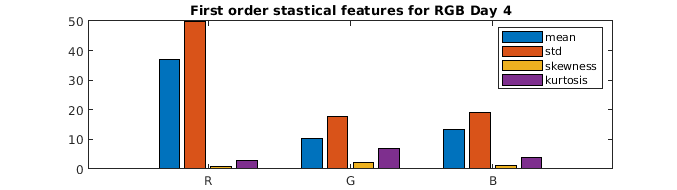

legend_given = ["Contrast","Correlation","Energy","Homogeneity"];

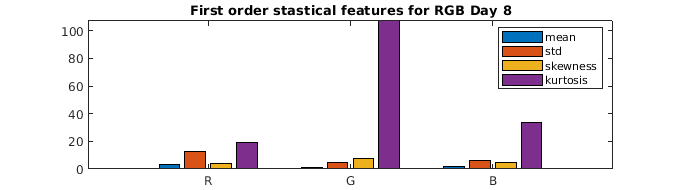

img0_sof = get_glcm_stats(seg0);
plot_bar(img0_sof, ["R","G","B"], "Second order GLCM based features for Day-0",legend_given);

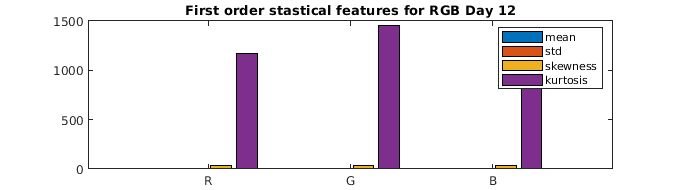

img4_sof = get_glcm_stats(seg4);
plot_bar(img4_sof, ["R","G","B"], "Second order GLCM based features for Day-4",legend_given);

img8_sof = get_glcm_stats(seg8);
plot_bar(img8_sof, ["R","G","B"], "Second order GLCM based features for Day-8",legend_given);
img12_sof = get_glcm_stats(seg12);
plot_bar(img12_sof, ["R","G","B"], "Second order GLCM based features for Day-12",legend_given);

### Observation on change of features with respect to Day of wound healing 

- As we go along from Day-0 to Day-12 we can observe the **size of wound** and it is **decreasing**. 

- So **Mean** and **Standard deviation** is **high** in Day-0 and Day-4. **Skewness** and **Kurtosis** is comparitively **low** becasue of good distibution of pixels around mean and lower standard deviation.

- The size of the wound is **small** and **very small **in **Day-8** and **Day-12** respectively. So **Mean** and **Standard** **devuiation** is low because of **lower** **no of** **pixels** contibuting and also wound becomes **darker** and coming close to **black** **level** as Days progress.

- As the pixels are near black level in** Day-12** , the **Kurtosis** is **very** **high** compared to other days.

- **Contrast** of in **Day-0** and** Day-4** is moderate due to **illumination** in the region and **near zero** in the Day-8 and Day-12.

- In the **Day-8** and **Day-12** the **local** **change** is **high** and can be seen as **high** **energy**.

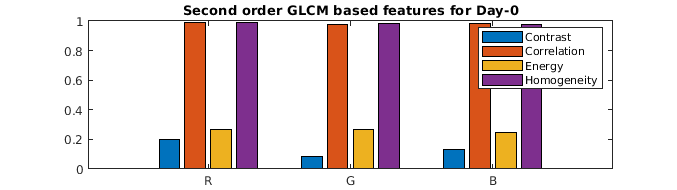

function NaN = plot_bar(features,labels,title_given,legend_given)
    X = categorical(labels);
    X = reordercats(X,labels);

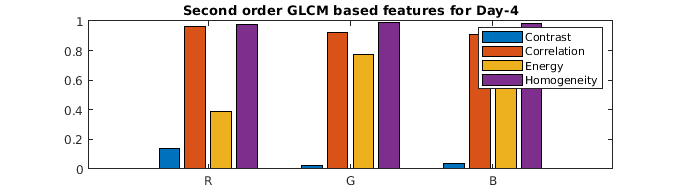

    bar(X,features);
    legend(legend_given);

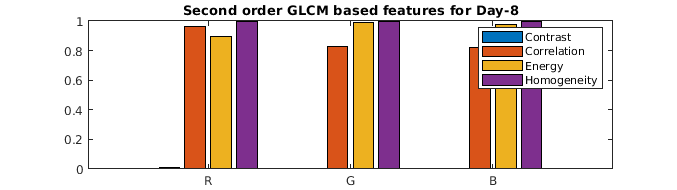

    title(title_given)
end

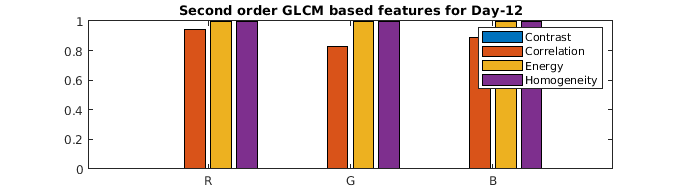

function stats_img = get_glcm_stats(img)
    c = 3;

    if length(size(img)) == 2
        c = 1;
    end
    stats_img = zeros(c,4);
    for i = 1:c
        stats = graycoprops(graycomatrix(img(:,:,i)));
        stats_img(i,:) = [stats.Contrast,stats.Correlation,stats.Energy,stats.Homogeneity];
    end
end

function features = get_first_features(img)
    c = 3;
    if length(size(img)) == 2
        c = 1;
    end
    ri = 0:255;
    %ri = transpose(ri);
    features = zeros(c,4);
    for i=1:c
        [counts,~] = imhist(img(:,:,i));
        counts = transpose(counts);
        pr = counts./sum(counts,"all");
        mu = sum(ri.*pr,"all");
        sd = sqrt(sum(((ri-mu).^2).*pr,'all'));
        skew = sum(((ri-mu).^3).*pr,"all")/(sd^3);
        kurt = sum(((ri-mu).^4).*pr,"all")/(sd^4);
        features(i,:) = [mu,sd,skew,kurt];
    end
end